Defining 2 classes:

x=linspace(-1,6,1000);
Normal=gampdf(x,16,1/8); %data2
Fault=gampdf(x,3,1/4); %data1

Plot the data

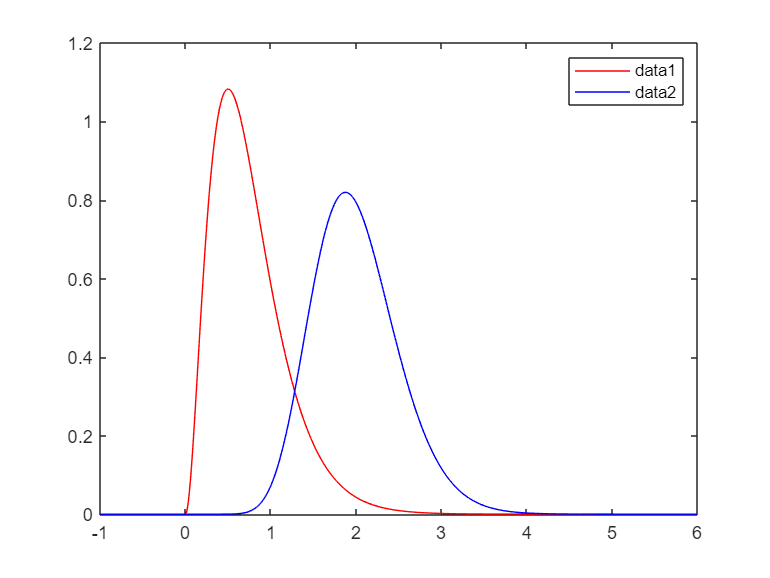

plot(x,Fault,'r',x,Normal,'b')
legend('show')

Finding the intersection of them. The functions are defined discretely. Thus, we must move along the push of one of function until reaching two points that are near to the intersection. With assuming P(Fault)=P(Normal) we have:

B=zeros;
c=1;
index=[];
for i=1:1000
    if Fault(i)>Normal(i)-0.01
        index(i)=i;
        B(i)=Fault(i);
        c=c+1;
    end
    
end 

As we have no knowledge of the location of intersection, there will be lots of zeros gots into B vector with this method that we don't want them. So, with this code, the unwanted data will be removed and. At the end, two points near to the intersection are two last member of B1 vector and their indexes are also two las member of index1.

B1=[];
index1=[];
c1=1;
for i=1:c-1
    if B(i)>0.1
        B1(c1)=B(i);
        index1(c1)=index(i);
        c1=c1+1;
    end
end
B1(c1-2:c1-1)

ans =     0.3154    0.3101


index1(c1-2:c1-1)

ans =    326   327


Since, these data are collected with this condition: Fault(i)>Normal(i)-0.01, there is a chance that the real intersction located between two points. Therefore, interpolation (even linear) can find the better answer than choosing one of them.

Beys_val=mean(B1(c1-2:c1-1))

Beys_val = 0.3127

thr_BD=mean(x(index1(c1-2:c1-1)))

thr_BD = 1.2808

The final result with Decision surface will be:

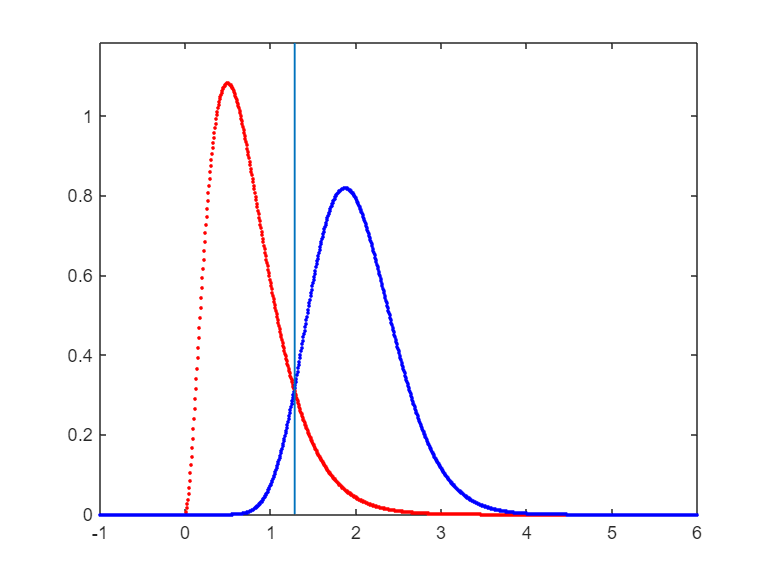

plot(x,Fault,'r.',x,Normal,'b.')
line([thr_BD thr_BD],[0 max([Fault,Normal])+0.1],'LineWidth',1)
ylim([0,max([Fault,Normal]+0.1)])

For this part, instead of trying a number for lambda, I try to find a minimum lambda that indicate x=1.2 as Normal. Here, in every loop about 0.0011 will be added to l and continoues the previous method to find the interscetion and checks the D.S if it's after x=1.2 or not. If it is, the loop continues and goes for the next j and if not, saves the value of lambda and stops the loop.

l=1;

for j=1:1000
Normal_new=(l+j/900)*gampdf(x,16,1/8); %data2
Fault_new=gampdf(x,3,1/4); %data1
% plot(x,Fault_new,'r.',x,Normal_new,'b.')
B_new=zeros;
c_new=1;
index_new=[];
for i=1:1000
    if Fault_new(i)>Normal_new(i)-0.01
        index_new(i)=i;
        B_new(i)=Fault_new(i);
        c_new=c_new+1;
    end
    
end 
B1_new=[];
index1_new=[];
c1_new=1;
for i=1:c_new-1
    if B_new(i)>0.1
        B1_new(c1_new)=B_new(i);
        index1_new(c1_new)=index_new(i);
        c1_new=c1_new+1;
    end
end

Beys_val_new=mean(B1_new(c1_new-2:c1_new-1));
thr_BD_new=mean(x(index1_new(c1_new-2:c1_new-1)));
if thr_BD_new<1.2
    l=l+j/900;
    break
end
end    

As we can see, the D.S. is 1.1967 and smaller than 1.2, therefore x=1.2 will indicates as Normal now. The minimum value of lambda is 1.6511 and of coure it's not the exact minimum value(because of the percision)

Beys_val_new

Beys_val_new = 0.3822

thr_BD_new

thr_BD_new = 1.1967

l

l = 1.6511

Two classes will reshape with lambda as follows:

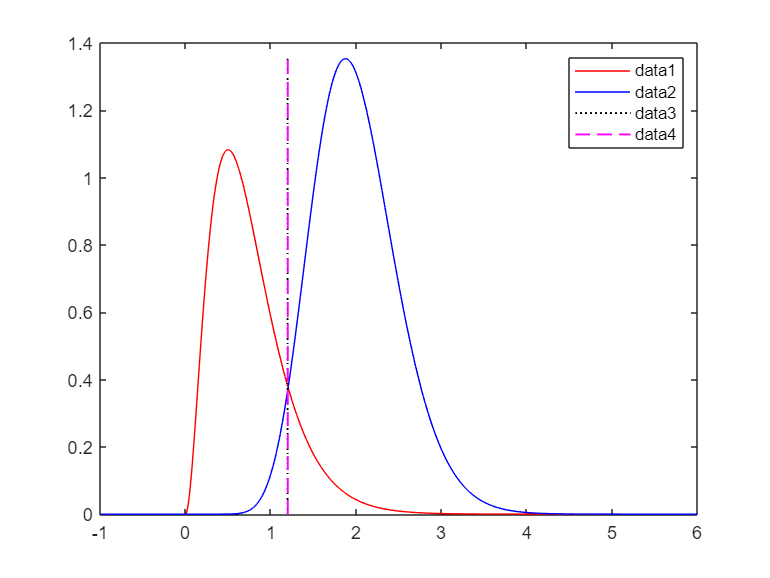

plot(x,Fault_new,'r',x,Normal_new,'b')
line([thr_BD_new thr_BD_new],[0 max([Fault_new,Normal_new])],'LineWidth',1,'Color','black','LineStyle',':') %data3
line([1.2 1.2],[0 max([Fault_new,Normal_new])],'LineWidth',1,'Color','m','LineStyle','--') %data4 where x=1.2
legend('show')